# Drive Pattern - Main Script

## Open Model and Run Simulation

mdl = "DrivePattern_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

% Load default parameters
DrivePattern_harness_setup

% Set up external input signals
vehSigBuilder = DrivePattern_InputSignalBuilder;
inputPatterns = [
  "Constant"
  "Accelerate_Decelerate"
  "Accelerate_Decelerate_Twice"
  "SimpleDrivePattern"
  "FTP75"
];
numSim = numel(inputPatterns);

% Create SimulationInput object for each simulation
clear simIn
%simIn(1:numSim) = Simulink.SimulationInput(mdl);  % error in R2022a.
simIn(1:numSim) = Simulink.SimulationInput(char(mdl));
for idx = 1 : numSim
  inpData = feval(inputPatterns(idx), vehSigBuilder);
  simIn(idx) = setVariable(simIn(idx), "drivePattern_Signals", inpData.Signals);
  simIn(idx) = setVariable(simIn(idx), "drivePattern_Bus", inpData.Bus);
  simIn(idx) = setVariable(simIn(idx), ...
    "drivePatternFromWorkspace", inpData.Options.useFromWorkspace);
  simIn(idx) = setModelParameter(simIn(idx), "StopTime",num2str(inpData.Options.StopTime_s));
end

% Run simulations
simOut = sim(simIn, "UseFastRestart","on", "ShowProgress","on");

[16-May-2022 13:13:46] Running simulations...
[16-May-2022 13:13:58] Completed 1 of 5 simulation runs
[16-May-2022 13:13:59] Completed 2 of 5 simulation runs
[16-May-2022 13:13:59] Completed 3 of 5 simulation runs
[16-May-2022 13:13:59] Completed 4 of 5 simulation runs
[16-May-2022 13:13:59] Completed 5 of 5 simulation runs


## Simulation Results

Constant


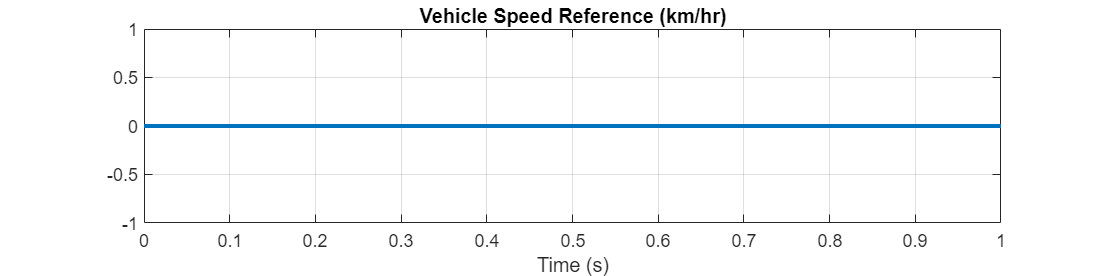

Accelerate_Decelerate


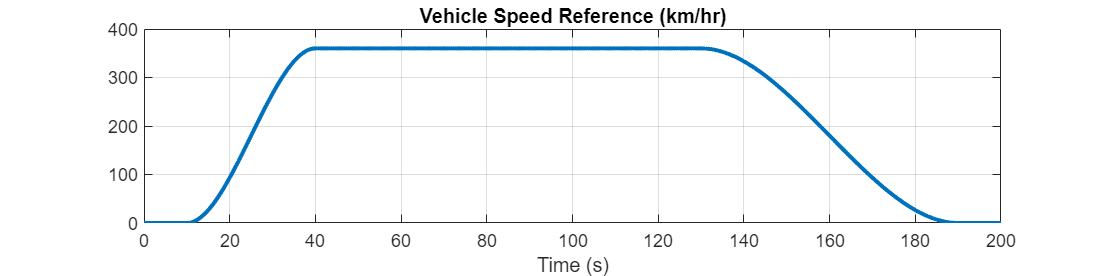

Accelerate_Decelerate_Twice


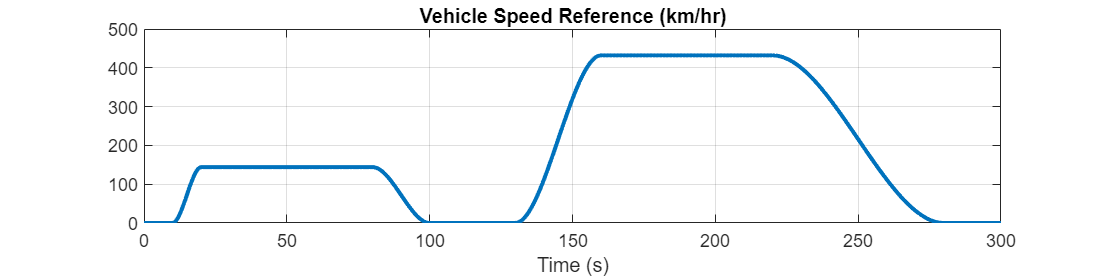

SimpleDrivePattern


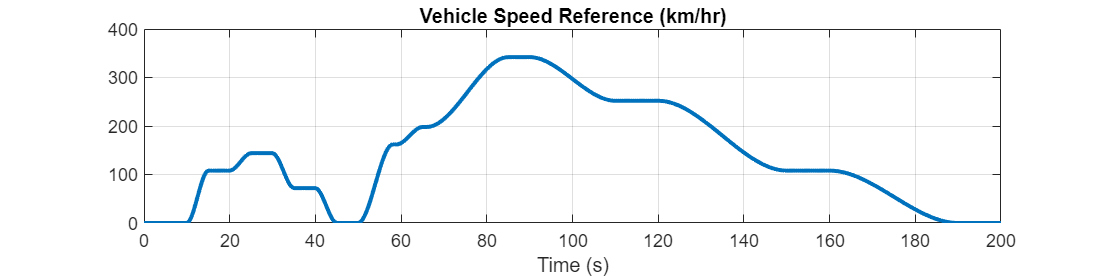

FTP75


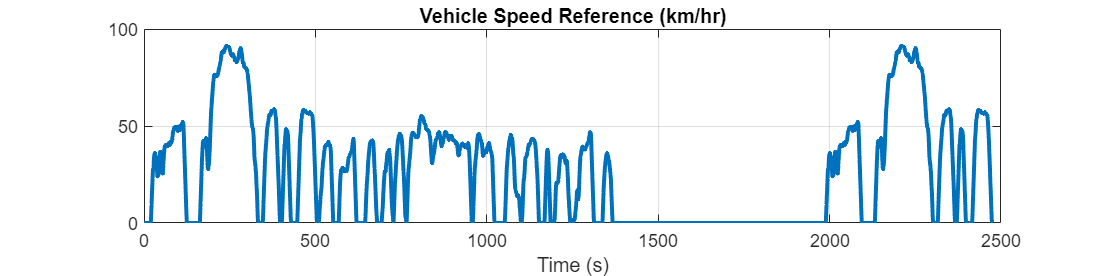

for idx = 1 : numSim
  disp(inputPatterns(idx))
  DrivePattern_plot_results(simOut(idx).logsout)
end

*Copyright 2021-2022 The MathWorks, Inc.*